# loading the dataset

clear; clc;
alpha = 30;
load(sprintf('C:\\Users\\Arshia\\Desktop\\StableLearningInBiologicalSNN\\Analysis\\Part3(ClassificationSequential)\\Data\\N400\\nMems25\\May_22_2025_07_40_41\\Recalls\\alpha%d\\recalls25.mat', alpha));
load('C:\Users\Arshia\Desktop\StableLearningInBiologicalSNN\Analysis\Part3(ClassificationSequential)\Data\N400\nMems25\May_22_2025_07_40_41\stimuli.mat')

% Define the folder path
folder = fullfile("Results", sprintf("Alpha%d", alpha));

% Create the folder if it doesn't exist
if ~exist(folder, 'dir')
    mkdir(folder);
end

t_min = 2.5*10^6; t_max = 2.5*10^6;
whos

  Name                      Size                 Bytes  Class          Attributes

  alpha                     1x1                      8  double                   
  delays                 5000x400             16000000  double                   
  firings              966979x2               15471664  double                   
  folder                    1x1                    182  string                   
  groups                    1x5000              270112  string                   
  orders_separate        5000x400             16000000  double                   
  orders_together        5000x400             16000000  double                   
  spikeCounts            5000x400             16000000  double                   
  stims                     1x25                   200  Stimulation              
  t_max                     1x1                      8  double                   
  t_min                     1x1                      8  double                   



# Computing the filtered raster plots


trials_list = 1:5:5000;
rasters = zeros(120000, length(trials_list));

for trial_idx = length(trials_list):-1:1
    trial = trials_list(trial_idx);
    idx = firings(:, 1) < t_min + trial*100 & firings(:, 1) > t_min + (trial-1)*100;
    ff = firings(idx, :); ff(:, 1) = ff(:, 1) - (t_min + (trial-1)*100);
    
    raster = LowPassFilter(ff);
    raster = raster(:);

    rasters(:, trial_idx) = raster;
end

function filtered = LowPassFilter(firings)
    firings = firings';
    T = 30;  % total duration
    dt = 0.1;                        % time resolution (1 ms)
    tau = 2;                      % van Rossum time constant
    time = dt:dt:T;                 % time vector
    n_T = length(time);
    
    n_neurons = 400;
    filtered = zeros(n_neurons, n_T);
    
    for i = 1:size(firings, 2)
        spike_time = firings(1, i);
        neuron = firings(2, i);
    
        % Convert spike time to index
        idx = round(spike_time / dt) + 1;
    
        % Add exponential response starting at spike
        if idx <= n_T
            decay_len = n_T - idx + 1;
            filtered(neuron, idx:end) = filtered(neuron, idx:end) + exp(- (0:decay_len-1) * dt / tau);
        end
    end
end

# Example Rater plot

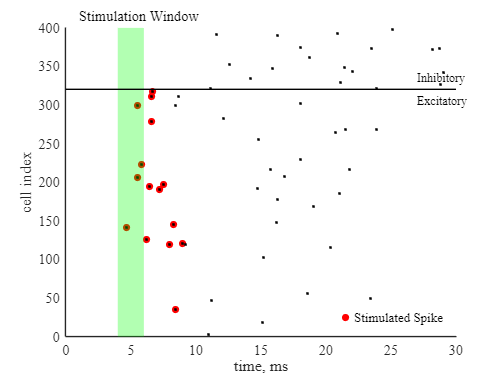

% Create new figure and hold to overlay multiple plots
figure; hold on;

% Extract stimulation timings and indices from the first pattern
pat_timings = stims(1).pattern_timings;
pat_indices = stims(1).pattern_indices;

% Flag for showing 'Stimulated Spike' in legend only once
HV = 'on';

% Loop through each stimulated neuron index
for i = 1:length(pat_indices)
    % Find spike times for the current stimulated neuron
    idx = ff(:, 2) == pat_indices(i);
    t0 = ff(idx, 1);
    
    % Skip if neuron did not spike
    if isempty(t0)
        continue;
    end
    
    % Use the first spike time only
    t0 = t0(1);
    
    % Only show spikes that occurred within 2 ms after stimulation onset
    if t0 < pat_timings(i) + 2 && pat_timings(i) < t0
        scatter(t0, pat_indices(i), 'red', 'filled', ...
            'HandleVisibility', HV, 'DisplayName', 'Stimulated Spike');
        HV = 'off'; % Hide further repeats from legend
    end
end

% Plot all spikes as small black dots
scatter(ff(:, 1), ff(:, 2), 'k.', 'HandleVisibility', 'off');

% Label axes
xlabel("time, ms");
ylabel("cell index");

% Set custom x-axis ticks
xticks(0:5:30);

% Highlight stimulation window using a transparent green box
fill([4, 4, 6, 6], [0, 400, 400, 0], ...
    'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none', ...
    'DisplayName', "Stimulation window", 'HandleVisibility', "off");

% Label the stimulation window
text(1, 415, "Stimulation Window", 'FontWeight', 'normal');

% Draw horizontal line to separate excitatory and inhibitory cells
plot([0 32], 320.5 * [1 1], ...
    'Color', [0 0 0 0.9], 'LineWidth', 0.5, 'HandleVisibility', 'off');

% Add text labels for cell types
text(27, 305, 'Excitatory', 'HorizontalAlignment', 'left', 'FontSize', 10);
text(27, 335, 'Inhibitory', 'HorizontalAlignment', 'left', 'FontSize', 10);

% Show legend (only includes 'Stimulat
% ed Spike' once)
legend('Box', 'off', 'Location', 'southeast', BackgroundAlpha=0.05, Color='k', EdgeColor='none');

% Remove tick marks but keep tick labels
ax = gca;
ax.TickLength = [0 0];

% Set x-axis limit
xlim([0 30]);

exportgraphics(gca, "Raster_Example.pdf")

# Raster Image Representation

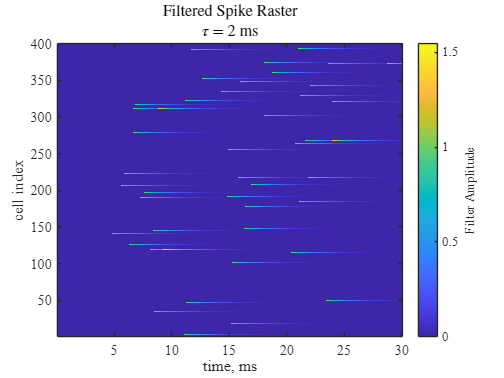

figure;
raster = reshape(raster, [400, 300]);
imagesc(raster)
xticks(0:50:300);  
xticklabels(0:5:30)
xlabel("time, ms");
ylabel("cell index");
cb = colorbar();

cb.Label.String = "Filter Amplitude";
title({"Filtered Spike Raster", '$\tau$ = 2 ms'}, 'Interpreter','latex', 'fontName', 'Times New Roman')
set(gca, 'ydir', 'normal', 'fontName', 'Times New Roman');
exportgraphics(gca, "Filtered_raster.pdf")

# Spike Count Representation

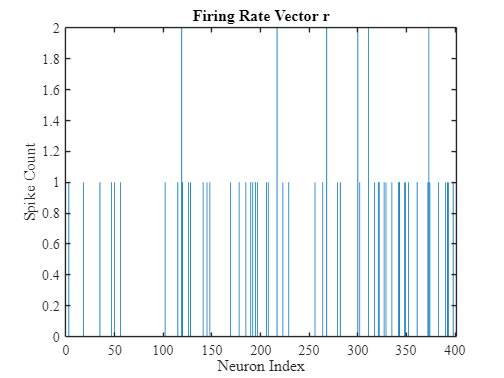

num_neurons = 400;  % assumes neuron indices are 1-based
r_vector = accumarray(ff(:,2), 1, [num_neurons, 1]);  % r(i) = spike count of neuron i

figure;
bar(1:num_neurons, r_vector)
xlabel('Neuron Index'); ylabel('Spike Count')
title('Firing Rate Vector r')

# Time Delay Representation

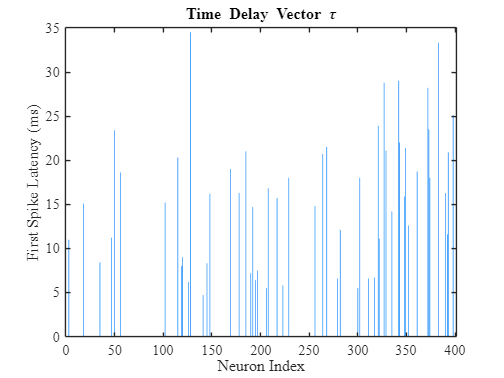

tau_vector = NaN(num_neurons, 1);  % preallocate with NaNs
for i = 1:num_neurons
    spikes = ff(ff(:,2) == i, 1);
    if ~isempty(spikes)
        tau_vector(i) = min(spikes);
    end
end


figure;
bar(1:400, tau_vector, 'FaceColor', [0.2 0.6 1])
xlabel('Neuron Index'); ylabel('First Spike Latency (ms)')
title('Time Delay Vector \tau')

# Order Representation

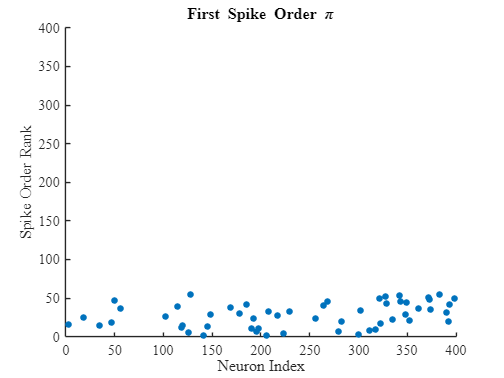

% Get index of neurons that fired at least once
spiking_idx = ~isnan(tau_vector);

% Get their first spike latencies
spike_latencies = tau_vector(spiking_idx);

% Sort only spiking neurons by their latency
[~, sort_order] = sort(spike_latencies);

% Create a rank vector, NaN by default
pi_vector = NaN(num_neurons, 1);

% Get the neuron indices of the spiking neurons
spiking_neuron_ids = find(spiking_idx);

% Assign ranks according to spike order
pi_vector(spiking_neuron_ids(sort_order)) = 1:sum(spiking_idx);

% Plot spike rank only for spiking neurons
figure;
scatter(spiking_neuron_ids, pi_vector(spiking_neuron_ids), 30, 'filled')
ylabel('Spike Order Rank'); xlabel('Neuron Index'); ylim([0 400])
title('First Spike Order \pi')

# Images (rasters) in PC space

% Perform PCA
[coeff, score, latent, tsquared, explained, mu] = pca(rasters', 'NumComponents', 2);

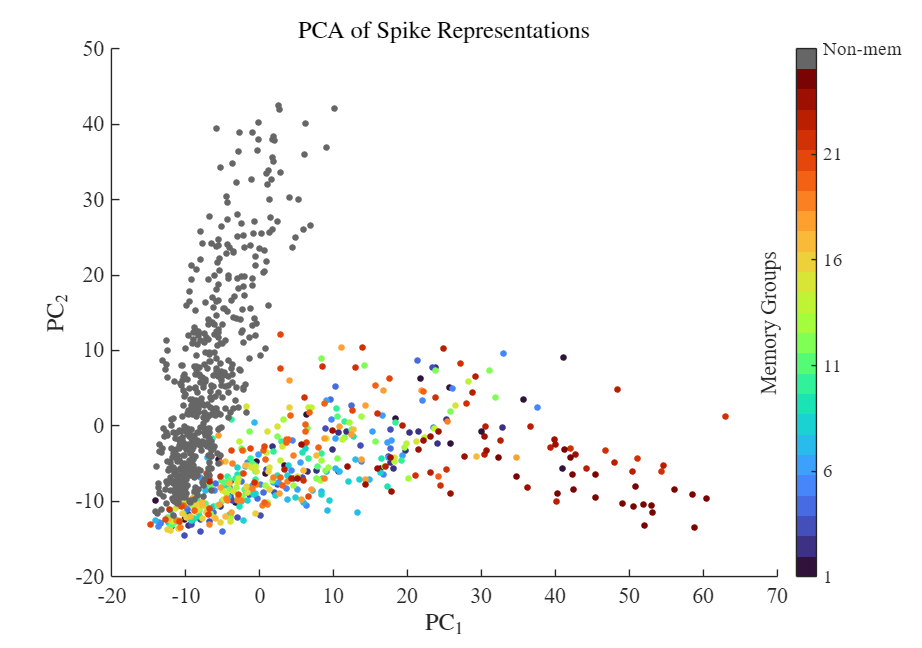

% Set group counts
n_memories = 25;
n_samples_per_class = length(trials_list) / 50;
n_non = 25;

% Total number of data points
group_labels = [repelem(1:n_memories, n_samples_per_class), ...
                repelem(n_memories + 1, n_non * n_samples_per_class)];  % 26 = non-memories

% Build colormap: turbo for memory, gray for non-memories
cmap = [turbo(n_memories); 0.4 0.4 0.4];  % darker gray for thesis printing

% Create figure
fig = figure('Units','normalized','Position',[0.1 0.1 0.4 0.5]);

% Plot
scatter(score(:,1), score(:,2), 30, group_labels, 'filled');  % Smaller size for dense plots

% Axes and Labels
xlabel('$\mathrm{PC}_1$', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
ylabel('$\mathrm{PC}_2$', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
title('PCA of Spike Representations', 'Interpreter', 'latex', 'FontSize', 20, 'FontName', 'Times New Roman');
set(gca, 'FontSize', 18, 'FontName', 'Times New Roman');

% Colorbar
colormap(cmap);
c = colorbar;
c.Ticks = [1:5:25, 26];
c.TickLabels = [string(1:5:25), "Non-mem"];
c.Label.String = 'Memory Groups';
% c.Label.Rotation = 270;
c.Label.FontSize = 18;
c.FontName = 'Times New Roman';
c.Location = "eastoutside";
c.Label.Position = [-2, 13];
% Save figure
exportgraphics(fig, fullfile(folder, sprintf("PCA_Alpha%d.png", alpha)), 'ContentType', 'image', 'Resolution', 600);
exportgraphics(fig, fullfile(folder, sprintf("PCA_Alpha%d.pdf", alpha)), 'ContentType', 'vector');

# Computing euclidean distance among rasters

mat = squareform(pdist(rasters', 'euclidean'));

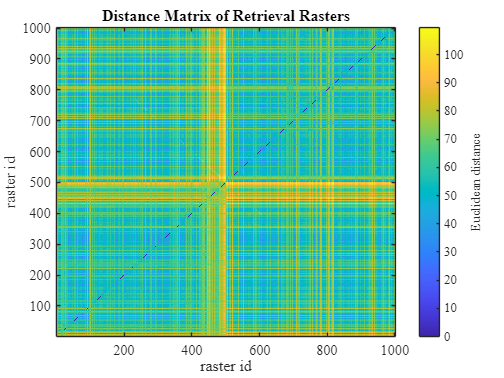

figure;
imagesc(mat);
cb = colorbar();
cb.Label.String = "Euclidean distance";
xlabel("raster id");
ylabel("raster id");
title("Distance Matrix of Retrieval Rasters")

set(gca, 'ydir', 'normal')

# Averaged distances within each memory group

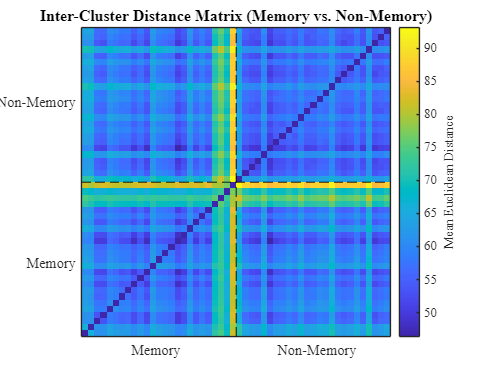

mat_averaged = blockproc(mat, [20 20], @(block) mean(block.data(:)));

temp = mat_averaged;
temp(eye(size(temp)) == 1) = nan;

fig = figure;
imagesc(temp);
axis square;
cb = colorbar();
cb.Label.String = "Mean Euclidean Distance";

xlabel("");
ylabel("");
title("Inter-Cluster Distance Matrix (Memory vs. Non-Memory)");

% Add dashed lines to separate memory vs non-memory blocks
xline(25.5, 'k--', 'LineWidth', 1);
yline(25.5, 'k--', 'LineWidth', 1);

% Optional: add memory vs non-memory labels
xticks([12.5 38.5]);
xticklabels({'Memory', 'Non-Memory'});
yticks([12.5 38.5]);
yticklabels({'Memory', 'Non-Memory'});

% Improve colormap and layout
colormap(parula);  % or turbo, hot, etc.
set(gca, 'YDir', 'normal', 'FontSize', 12, 'TickLength', [0 0]);

% Save the figures
exportgraphics(fig, fullfile(folder, sprintf("InterDistances_Alpha%d.png", alpha)), 'ContentType', 'image');
exportgraphics(fig, fullfile(folder, sprintf("InterDistances_Alpha%d.pdf", alpha)), 'ContentType', 'vector');

# Intra distances of clusters (it seems it fails to have the trend we found earlier with just delay representation)

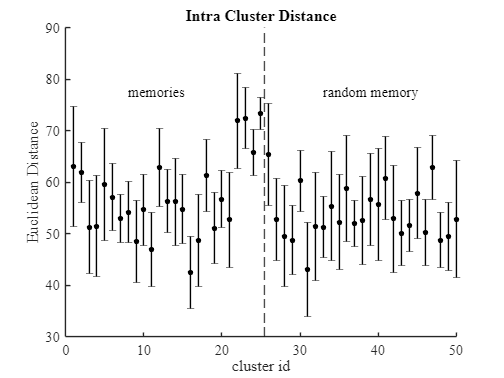

fig = figure; hold on;
for i = 1:50
    idx = (1:n_samples_per_class) + (i-1)*n_samples_per_class;
    submat = mat(idx, idx);
    intras = submat(triu(submat, 1) ~= 0);
    scatter(i, mean(intras), 20, 'ko', 'filled');
    errorbar(i, mean(intras), std(intras), std(intras), 'k');
end
xline(25.5, 'k--')

xlabel("cluster id");
ylabel("Euclidean Distance");
title("Intra Cluster Distance")
text(8, 77.5, "memories")
text(8+25, 77.5, "random memory")
set(gca, 'FontName', 'Times New Roman');
% Save the figures
exportgraphics(fig, fullfile(folder, sprintf("IntraDistances_Alpha%d.png", alpha)), 'ContentType', 'image');
exportgraphics(fig, fullfile(folder, sprintf("IntraDistances_Alpha%d.pdf", alpha)), 'ContentType', 'vector');

# Dendogram of the clusters

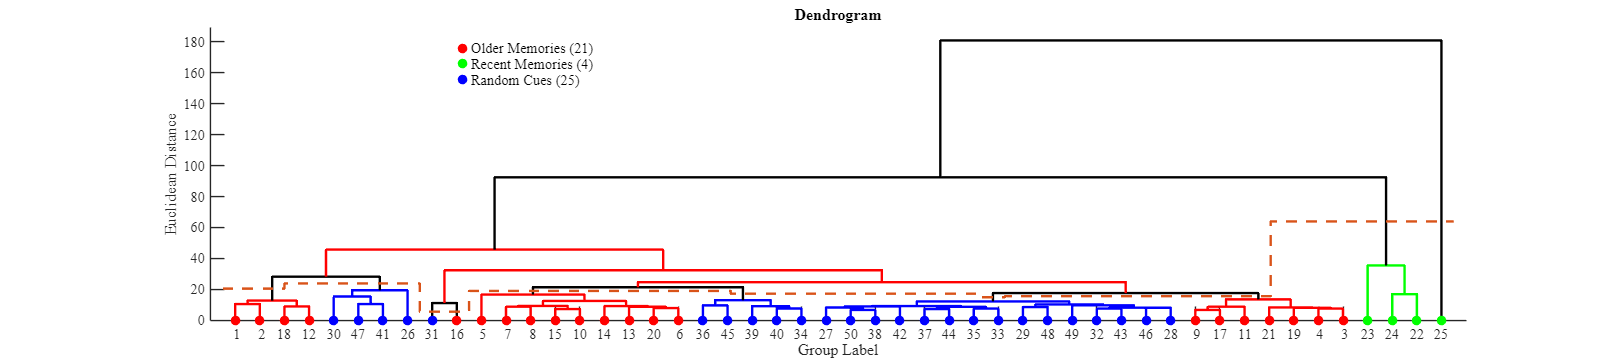

% Linkage (you already did this)
tree = linkage(mat_averaged, 'average', 'euclidean');

% Range of distances to sweep through
maxDist = max(tree(:,3));
thresholds = linspace(1, maxDist, 200);  % 200 steps
n_clusters = zeros(size(thresholds));

for i = 1:length(thresholds)
    T_temp = cluster(tree, 'cutoff', thresholds(i), 'criterion', 'distance');
    n_clusters(i) = numel(unique(T_temp));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot dendrogram
fig= figure('Position', [0, 0, 1800, 400]);

% Define cluster assignments (aligned with original data order)
clusterIndices = [repmat(1, 1, 21), repmat(2, 1, 4), repmat(3, 1, 25)]';
% clusterIndices = [repelem(1:50, 1, 20)];
% clusterIndices = cluster(tree, maxclust=3);

% Plot dendrogram with cluster coloring
[H, T, outperm] = dendrogram(tree, 0, ...
    'Orientation', "top", ...
    'ClusterIndices', clusterIndices, ...
    'ShowMarkers', true, ...
    'ShowCut', true);
set(H,LineWidth=2);

% Label axes
ylabel("Euclidean Distance", 'FontName', "Times New Roman", 'FontSize', 14);
xlabel("Group Label", 'FontName', "Times New Roman", 'FontSize', 14);
title('Dendrogram', 'FontName', "Times New Roman", 'FontSize', 16);

% Customize x-axis tick labels
ax = gca;
ax.XRuler.Axle.Visible = 'off';
ax.XTickLabelRotation = 0;  % Horizontal labels
set(gca, 'FontName', "Times New Roman", 'FontSize', 12);

counts= groupcounts(clusterIndices)';
% Add legend
legend(["Older Memories", "Recent Memories", "Random Cues"] + " (" + string(counts) + ")", ...
    'Box', 'off', ...
    'Location', 'best', ...
    'FontName', "Times New Roman", ...
    'FontSize', 12);

% Save the figures
exportgraphics(fig, fullfile(folder, sprintf("dendogram_Alpha%d.png", alpha)), 'ContentType', 'image');
exportgraphics(fig, fullfile(folder, sprintf("dendogram_Alpha%d.pdf", alpha)), 'ContentType', 'vector');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Plot cluster count vs. distance
% subplot(2,1,2);
% plot(thresholds, n_clusters, 'LineWidth', 2);
% xlabel('Linkage Distance (Cutoff)');
% ylabel('Number of Clusters');
% title('Number of Clusters vs. Distance Threshold');
% grid on;


# mdscale

Y = mdscale(mat, 2); % classical MDS

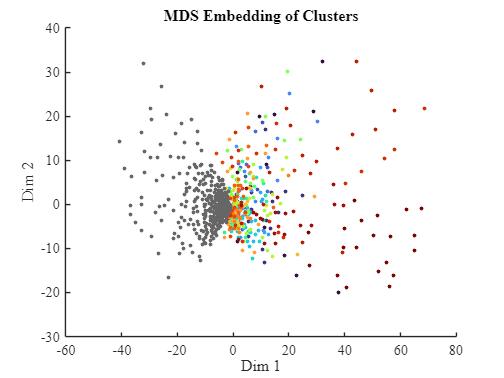

figure;
scatter(Y(:,1), Y(:,2),10, group_labels,'filled');
colormap(cmap);

title('MDS Embedding of Clusters');
xlabel('Dim 1'); ylabel('Dim 2');

# t-sne !


Y = tsne(rasters', 'Algorithm', 'exact','Distance', 'euclidean');  % D must be symmetric

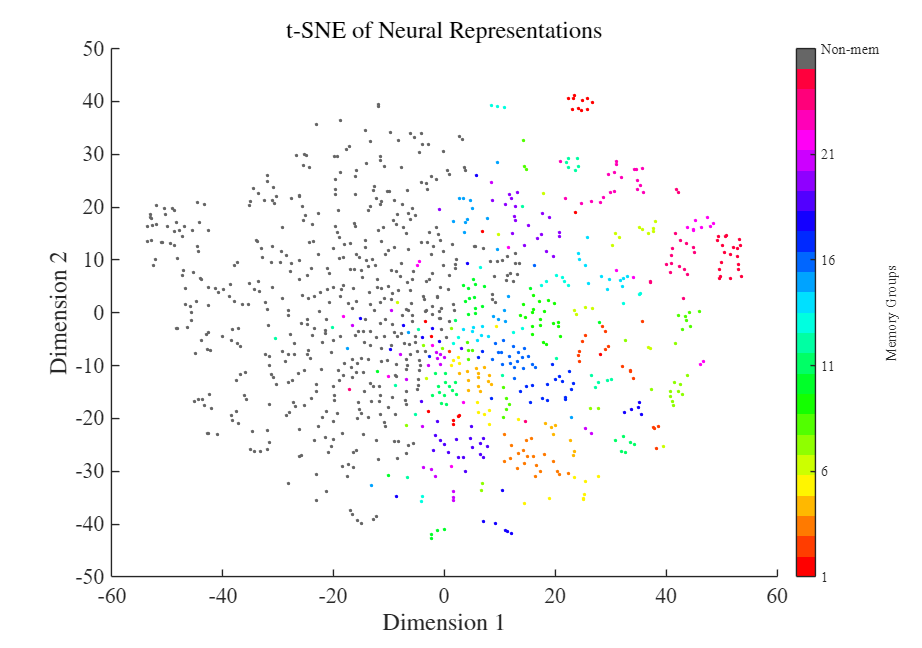

fig = figure('Units','normalized','Position',[0.1 0.1 0.4 0.5]);

% Assign group indices (1–25 for memory groups, 26 for non-memories)
labels = [repelem(1:25, 20), repelem(26, 500)]';  % 1000 samples total

% Define colormap: 25 hsv colors + gray
cmap = [hsv(25); 0.4 0.4 0.4]; % slightly darker gray for print

% Scatter using group index as color
scatter(Y(:,1), Y(:,2), 8, labels, 'filled');  % increased marker size

% Apply colormap and colorbar
colormap(cmap);
c = colorbar;
c.Ticks = [1:5:25, 26];
c.TickLabels = [string(1:5:25), "Non-mem"];
c.Label.String = 'Memory Groups';
% c.Label.Rotation = 0;
% c.Label.Position = [1.0 * max(Y(:,1)), 0]; % Adjust position if needed
c.FontName = 'Times New Roman';
c.FontSize = 12;

% Styling
title('t-SNE of Neural Representations', 'FontSize', 20, 'Interpreter', 'latex', 'FontName', 'Times New Roman');
xlabel('Dimension 1', 'FontSize', 18, 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel('Dimension 2', 'FontSize', 18, 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'FontName', 'Times New Roman', 'FontSize', 18);

exportgraphics(fig, fullfile(folder, sprintf("tsne_Alpha%d.png", alpha)), 'ContentType', 'image', 'Resolution', 600);
exportgraphics(fig, fullfile(folder, sprintf("tsne_Alpha%d.pdf", alpha)), 'ContentType', 'vector');

# Laplacian Eigenmap

D = squareform(pdist(rasters'));  % or use your own D

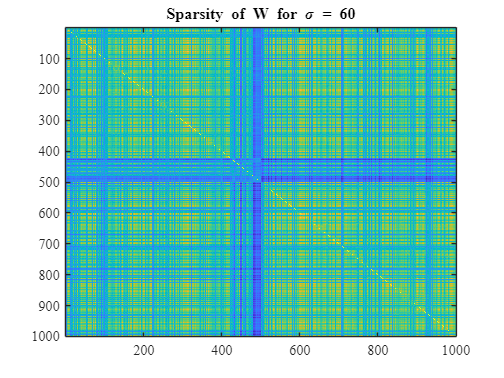


sigma = 60;
W = exp(-D.^2 / (2*sigma^2));  % similarity matrix

figure;
imagesc(W);  % threshold very small weights
title(['Sparsity of W for \sigma = ', num2str(sigma)]);


Dg = diag(sum(W, 2));

L = Dg - W;
L = L + 1e-5 * eye(size(L));

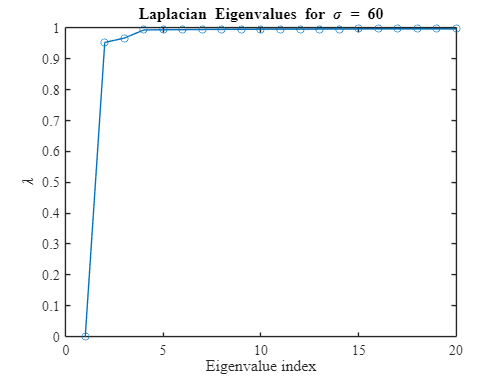

all_eigvals = eig(L, Dg);
all_eigvals = sort(real(all_eigvals));
figure;
plot(all_eigvals(1:20), 'o-');
title(['Laplacian Eigenvalues for \sigma = ', num2str(sigma)]);
ylabel('\lambda');
xlabel('Eigenvalue index');

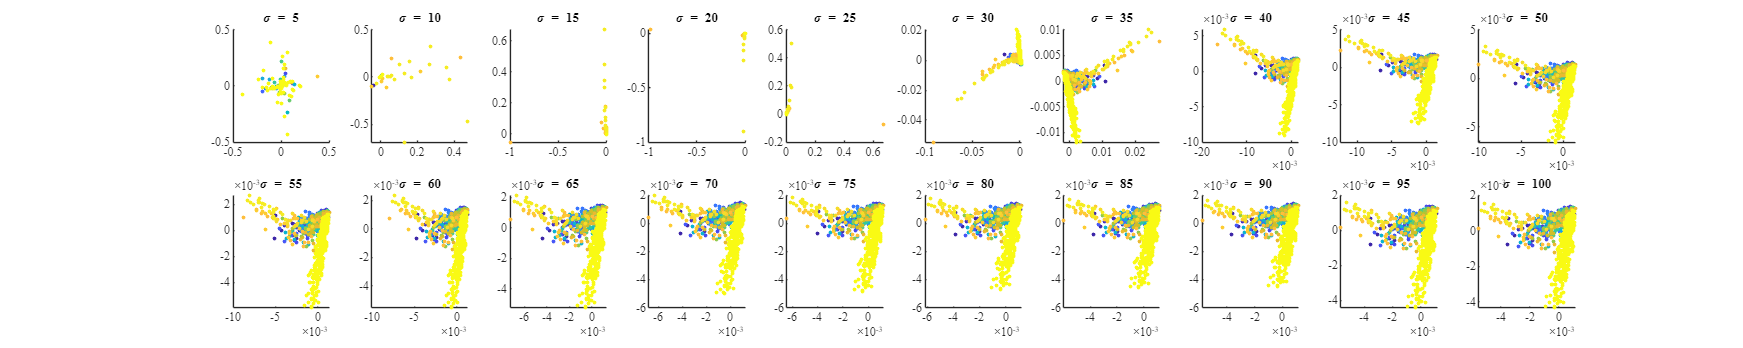

sigmas = 5:5:100;
figure(Position=[0, 0, 2000, 400]);
for s = sigmas
    sigma = s;
    W = exp(-D.^2 / (2*sigma^2));
    Dg = diag(sum(W, 2));
    L = Dg - W + 1e-5*eye(size(D));
    [eigVecs, ~] = eigs(L, Dg, 3, 'smallestabs');
    Y = eigVecs(:, 2:3);

    subplot(2, ceil(length(sigmas)/2), find(s == sigmas));
    scatter(Y(:,1), Y(:,2), 10, group_labels, 'filled');
    title(['\sigma = ', num2str(s)]);
end

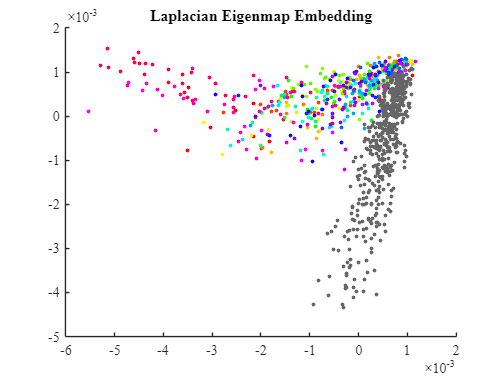


[eigVecs, eigVals] = eigs(L, Dg, 3, 'smallestabs');  % Get first nontrivial 2 components
embedding = eigVecs(:, 2:3);  % skip the first (trivial) eigenvector

figure;
scatter(embedding(:,1), embedding(:,2), 10, group_labels, 'filled');
colormap(cmap);
title('Laplacian Eigenmap Embedding');